# Circuit Demo

The purpose of this file is to demonstrate Laplace domain matching of cascaded S-parameters. Two circuits are created, fit with a rational function, and then are cascaded into a two port network which can optimized for.

## Create A Circuit

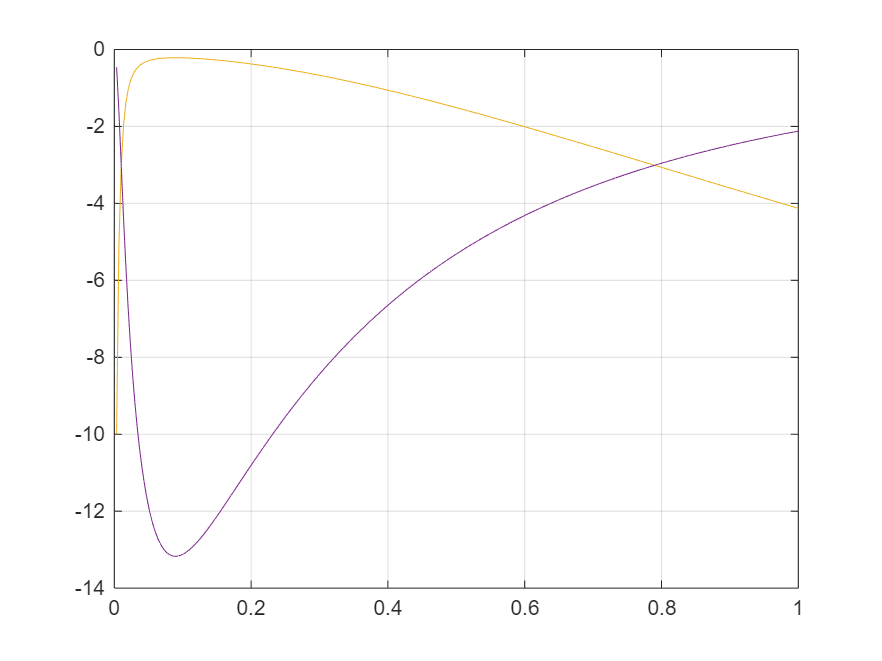


freqs = linspace(0, 1, 300);
s = tf('s');
Z1 = 0.05*s;
Z2 = 1/(1*s);
Z3 = 1/(0.05*s);
A = 1+Z1/Z3;
B = Z1+Z2+Z1*Z2/Z3;
C = 1/Z3;
D = 1+Z2/Z3;
O = [freqresp(A,freqs), freqresp(B,freqs); freqresp(C,freqs), freqresp(D,freqs)];
s1 = sparameters(abcd2s(O, 50),freqs);
plot(freqs, db(squeeze(s1.Parameters(1,1,:))), freqs, db(squeeze(s1.Parameters(1,2,:))), ...
    freqs, db(squeeze(s1.Parameters(2,1,:))), freqs, db(squeeze(s1.Parameters(2,2,:)))); grid on;